# Hurricane Harvey Report

## Importing and data processing

events = importfile("StormEvents_2017_finalProject.csv");

% Put months in correct order
monthOrder = ["January", "February", "March", "April", "May", "June", "July",...
    "August", "September", "October", "November", "December"];
events.Month = reordercats(events.Month, monthOrder);

% Set missing Property and Crop Cost to $0
events.Property_Cost(ismissing(events.Property_Cost)) = 0;
events.Crop_Cost(ismissing(events.Crop_Cost)) = 0;
% Add total damage to the table
events.Total_Damage = events.Property_Cost + events.Crop_Cost;
harveyEvents = events(events.Begin_Date_Time >= "2017-08-17 00:00:00" & events.End_Date_Time < "2017-09-04 00:00:00", :);
head(harveyEvents)

ans = 8×25 table
    EpisodeID      Event_ID      State      Year    Month        Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                            

### Two States Most Impacted by Harvey

groupsummary(harveyEvents,"State","sum","Total_Damage");
ans = sortrows(ans,'sum_Total_Damage','descend');
head(ans)

ans = 8×3 table
        State         GroupCount    sum_Total_Damage
    ______________    __________    ________________

    TEXAS                272           7.7493e+10   
    LOUISIANA             85           7.5277e+07   
    NEBRASKA              62           1.6154e+07   
    NORTH CAROLINA        59           1.2338e+07   
    WASHINGTON             2                4e+06   
    FLORIDA               68            2.237e+06   
    MINNESOTA             24            1.625e+06   
    MISSISSIPPI           39             9.15e+05   


*So the most impacted states are Texas and Louisiana.*

### Table of Events for Two Most Impacted States

texasLouisianaevents = harveyEvents(ismember(harveyEvents.State,{'LOUISIANA','TEXAS'}),:);
head(texasLouisianaevents)

ans = 8×25 table
    EpisodeID      Event_ID     State    Year    Month        Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                               

## Visualizations

We will use Histograms, Pie Charts and Geographic plots.

### Figures of Event Types

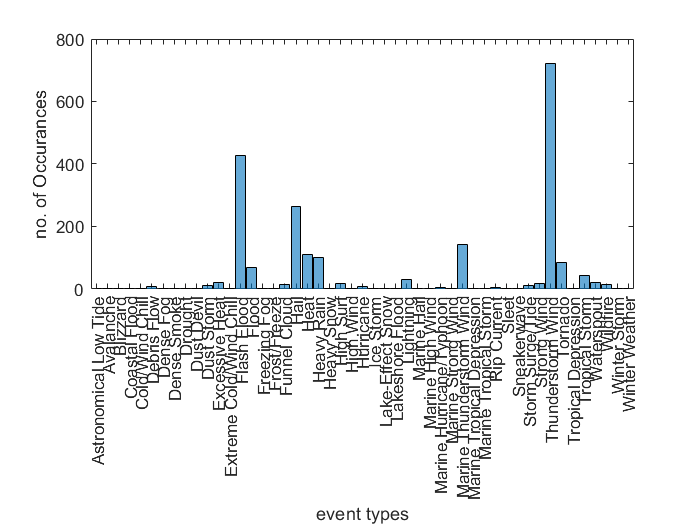

% Histogram of Event Types distribution due to the Hurricane - Harvey, 
% in all of USA
histogram(harveyEvents.Event_Type)
xlabel('event types')
ylabel('no. of Occurances')

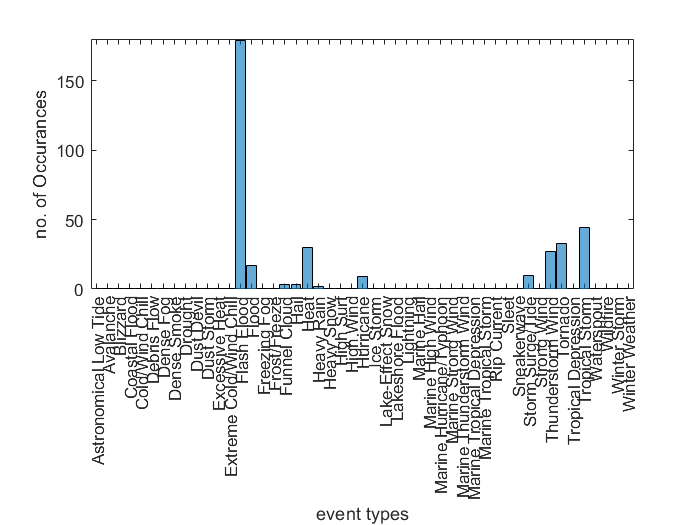

% Histogram of Event Types distribution due to the Hurricane - Harvey, 
% in the states of Texas and Louisiana
histogram(texasLouisianaevents.Event_Type)
xlabel('event types')
ylabel('no. of Occurances')

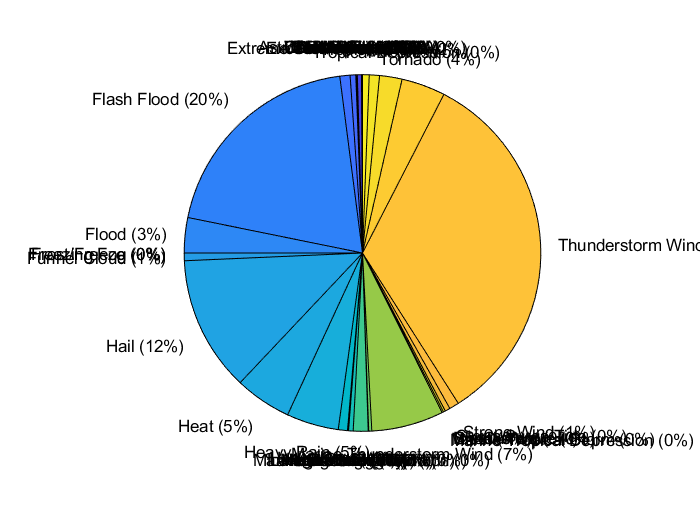

% Pie Chart on the distribution of event types due to Hurricane - Harvey,
% in all of USA
pie(harveyEvents.Event_Type)

The overall effect of the hurricane must have been thunderstorms and winds.

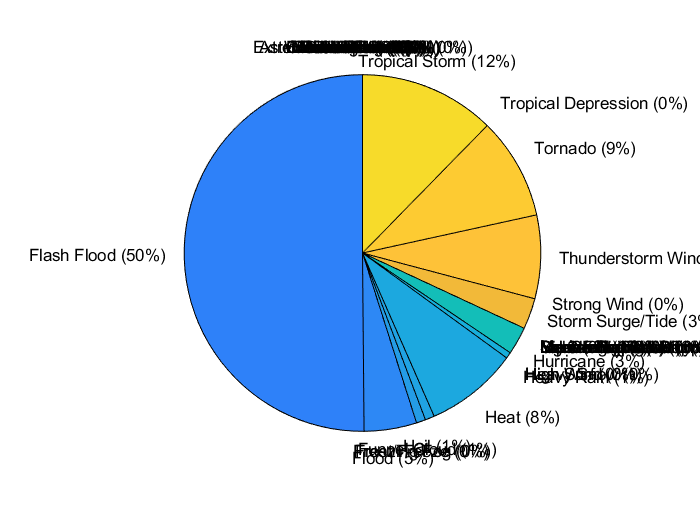

% Pie Chart on the distribution of event types due to Hurricane - Harvey,
% in the states of Texas and Louisiana
pie(texasLouisianaevents.Event_Type)

So most of the damage in Texas and Louisiana must have been due to floods.

### Figures of Event Locations

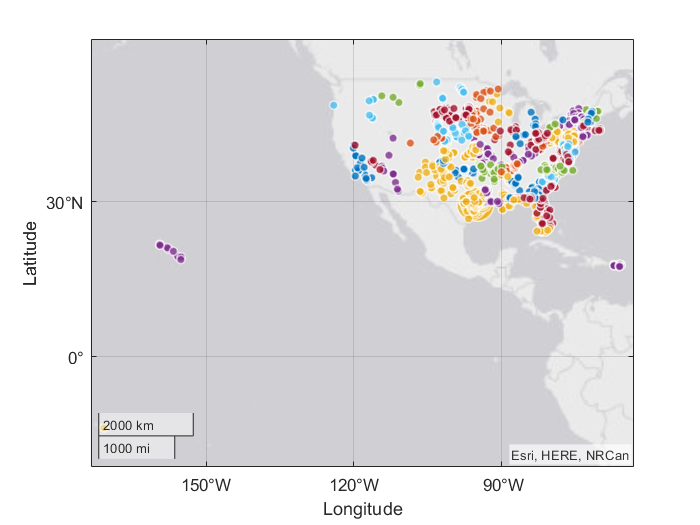

% Geographic plot of the event START locations 
% due to the Hurricane - Harvey,
% in all of USA
geobubble(harveyEvents.Begin_Lat,harveyEvents.Begin_Lon,harveyEvents.Total_Damage,harveyEvents.State);

The eastern coastal states have had more effect than the rest of USA.

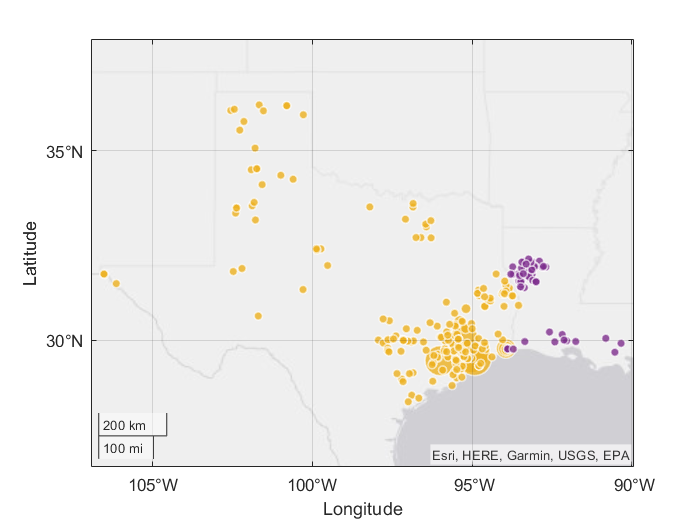

% Geographic plot of the event START locations 
% due to the Hurricane - Harvey,
% in the states of Texas and Louisiana
geobubble(texasLouisianaevents.Begin_Lat,texasLouisianaevents.Begin_Lon,texasLouisianaevents.Total_Damage,texasLouisianaevents.State);

And inside the most affected states, their eastern coast have had the most casualities.

## Analysis

We will use tables to analyse the follwing.

### Three Counties with Most Events in Texas

texasEvents = texasLouisianaevents(texasLouisianaevents.State ~= 'LOUISIANA',:);
groupsummary(texasEvents,"CZ_Name");
ans = sortrows(ans,'GroupCount','descend');
head(ans)

ans = 8×2 table
     CZ_Name     GroupCount
    _________    __________

    HARRIS           21    
    GALVESTON        17    
    FORT BEND        13    
    ANGELINA         12    
    BRAZORIA         12    
    SABINE           12    
    BASTROP           9    
    CHAMBERS          8    


Harris, Galveston, Fort Bend have had the most events in Texas due to the Hurricane - Harvey.

### Three Counties with Most Events in Louisiana

louisianaEvents = texasLouisianaevents(texasLouisianaevents.State ~= 'TEXAS',:);
groupsummary(louisianaEvents,"CZ_Name");
ans = sortrows(ans,'GroupCount','descend');
head(ans)

ans = 8×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    VERMILION            4    
    CAMERON              3    
    DE SOTO              3    
    UNION                2    


Natchitoches, Sabine and Red River have had the most events in Louisiana due to the Hurricane - Harvey.

### Three Counties with Highest Property Cost in Texas

groupsummary(texasEvents,"CZ_Name","sum","Property_Cost");
ans = sortrows(ans,'sum_Property_Cost','descend');
head(ans)

ans = 8×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17                2e+10    
    FORT BEND         13           1.6004e+10    
    MONTGOMERY         6              1.4e+10    
    HARRIS            21           1.0001e+10    
    JEFFERSON          4                3e+09    
    BRAZORIA          12           2.0008e+09    
    ARANSAS            2             1.95e+09    
    ORANGE             2              1.5e+09    


Galveston, Fort Bend and Montgomery have had the highest reported property costs in the state of Texas due to the Hurricane - Harvey. The costs being $20B, $16004M and $14B respectively. 

### Three Counties with Highest Property Cost in Louisiana

groupsummary(louisianaEvents,"CZ_Name","sum","Property_Cost");
ans = sortrows(ans,'sum_Property_Cost','descend');
head(ans)

ans = 8×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1                6e+07     
    BEAUREGARD        1              1.5e+07     
    ACADIA            1                2e+05     
    CAMERON           3                72000     
    VERMILION         4                 5000     
    BIENVILLE         1                    0     
    BOSSIER           1                    0     
    CADDO             1                    0     


Calcasieu, Beauregard and Acadia have had the highest reported property costs in the state of Louisiana due to the Hurricane - Harvey. The costs being $60M, $15M and $200K respectively. 

## Conclusions and Recommendations

Hence from the above analysis we can say that the south eastern coast has had the maximum casualities due to the Hurricane - Harvey. The resources can be allocated to the countries of Galveston, Fort Bend and Montgomery in Texas, and to the countries of Calcasieu, Beauregard and Acadia in  Louisiana in top priority. And then to Harris in Texas and Natchitoches, Sabine and Red River in Louisiana next. There after to other parts of these two states and other states.